# Graph Connectivity Analysis Demo

### Non-SSR Digraph Example

A=[0 1 0 0 0 0 0;
   0 0 1 0 0 0 0; 
   1 0 0 0 0 0 0; 
   0 0 1 0 0 1 0; 
   0 0 0 1 0 0 0; 
   0 0 0 0 1 0 1; 
   1 0 0 0 0 0 0];
sc=cDigraphAnalysis(A);
[res,src,out]=sc.isProductive;
fprintf('Productive Graph: %s',mat2str(res));

Productive Graph: false

if ~isempty(src)
fprintf('Unreachable nodes from IN: %s\n',strjoin(src));end

Unreachable nodes from IN: N4 N5 N6 OUT


if ~isempty(out)
fprintf('Nodes that do not reach OUT: %s\n',strjoin(out));end

Nodes that do not reach OUT: IN N1 N2 N3


#### Plot Digraph

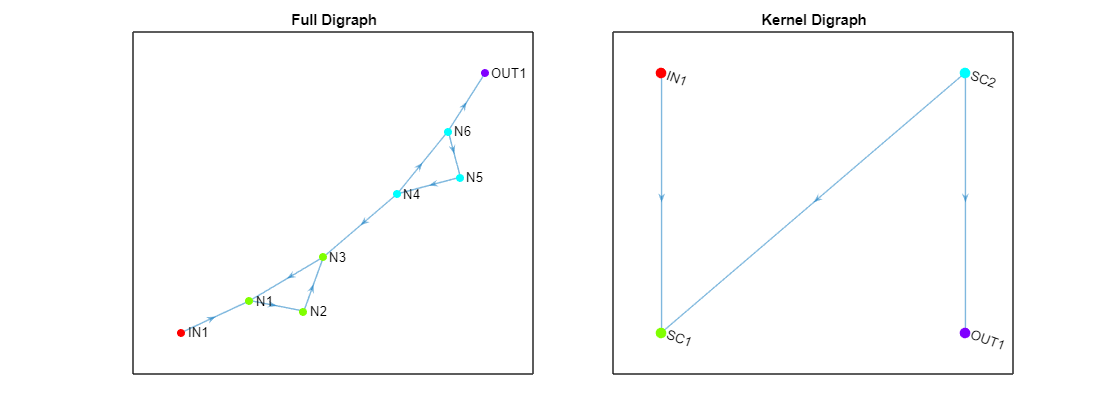

p=gcf().Position;
figure("Position",[0,0,2*p(3),p(4)])

tiledlayout(1,2,"TileSpacing","compact") 
nexttile;
sc.plotGraph;
title('Full Digraph')
nexttile
sc.plotKernelGraph;
title('Kernel Digraph')

### Productive Graph Example

A=[0 1 0 0 0 0 0; 
   0 0 1 0 0 0 1; 
   1 0 0 1 0 0 0; 
   0 0 0 0 0 1 0; 
   0 0 0 1 0 0 0; 
   0 0 0 0 1 0 1; 
   1 0 0 0 1 0 0];
sc=cDigraphAnalysis(A);
fprintf('Productive Graph: %s',mat2str(sc.isProductive));

Productive Graph: true

#### Plot Digraph

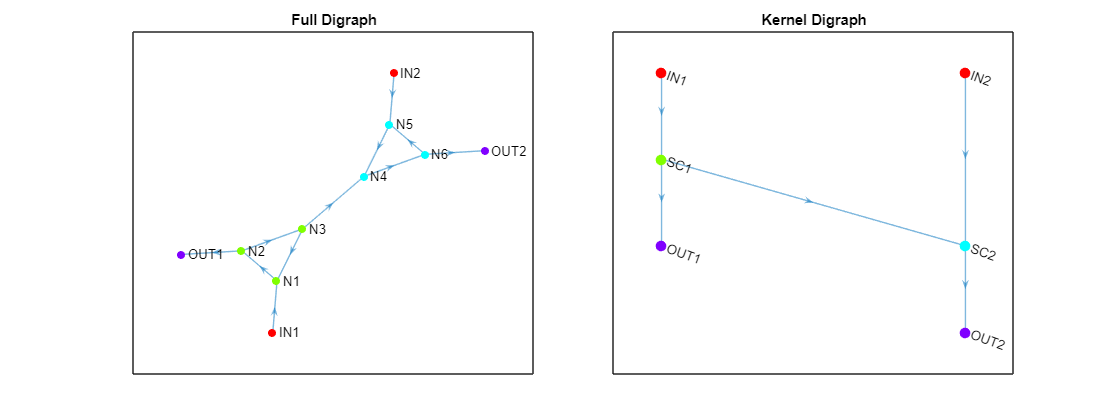

tiledlayout(1,2,"TileSpacing","compact") 
nexttile;
sc.plotGraph;
title('Full Digraph');
nexttile;
sc.plotKernelGraph;
title('Kernel Digraph')

printTable(sc.getGroupsTable);


Graph Components

 Name   Component  
—————————————————————
 IN1    IN         
 IN2    IN         
 N1     SC1        
 N2     SC1        
 N3     SC1        
 N4     SC2        
 N5     SC2        
 N6     SC2        
 OUT1   OUT        
 OUT2   OUT        

